# **Rozwiązywanie Układów Równań Liniowych**

Równanie liniowe zawiera jedynie dwie kategorie składników:

**Stałe** - liczby niezmienne, które mogą występować samodzielnie w równaniu.

**Zmienne przemnożone przez stałe** - wyrażenia, w których zmienne występują pomnożone przez stałe współczynniki.

**Układy równań liniowych**

Równanie liniowe zawiera jedynie składniki, które są albo wielokrotnościami zmiennych, albo stałymi. 

Można je zapisać w postaci:


$$\[
a_1 x_1 + a_2 x_2 + a_3 x_3 + \ldots = b
\]$$


$a_i$ - są stałymi;

$x_i$ - są zmiennymi;

**Przykład równania liniowego:**


$$2 \cdot x + 5 - y = 0 $$


Aby rozwiązać równanie, należy wyznaczyć jedną ze zmiennych (np. y) w zależności od pozostałych.

Przekształcamy je do postaci, w której wyrażamy y:


$$ y = 2 \cdot x + 5 $$


Jest to rozwiązanie równania dla zmiennej y jako funkcji x. 

Rozwiązanie można wyznaczyć dla jednej wartości x, lub zbioru wartości x. 

Można również interpretować jako równanie prostej na płaszczyźnie, gdzie współczynnik kierunkowy wynosi 2, a wyraz wolny wynosi 5.

**Rozwiązanie układu równań liniowych **

Aby rozwiązać **układ** równań **liniowych** w MATLAB, należy najpierw przekształcić go do postaci macierzowej. 

Zapisujemy układ w postaci równań:


$$Ax = b$$


gdzie:

**A** to macierz współczynników,

**x** to wektor niewiadomych,

**b** to wektor wartości po prawej stronie równań.

W MATLAB-ie operator `\` pozwala rozwiązać równanie macierzowe Ax = b dla wektora niewiadomych **x**.

**Przykład 1.**

Rozwiązywanie układów równań liniowych.

Podstawową metodą jest przedstawienie układu jako macierzy, gdzie poszczególne kolumny odpowiadają wartością przy tych samych zmiennych w każdym równaniu.

 Przykładowo, układ równań:

3a +2b - c = 1

2a - 2b + 4c = -1

a + c = 0,5

zapiszemy w postaci macierzy w poniższy sposób:

A = [3 2 -1;2 -2 4;1 0 1];

Następnie należy utworzyć wektor zawierający wartości stałych z powyższych równań

b = [1;-1;0.5];

Przyjmując wektor X = [a;b;c], wiemy, że:

X = A^-1 * B

zatem możemy uzyskać wektor rozwiązań w poniższy sposób:

X = inv(A) * b

X =    -0.7500
    2.2500
    1.2500


Alternatywnie, ten sam efekt możemy uzyskać za pomocą znaku "\"

X2 = A\b

X2 =    -0.7500
    2.2500
    1.2500


**Przykład 2**

 Należy rozwiązać układ równań liniowych:

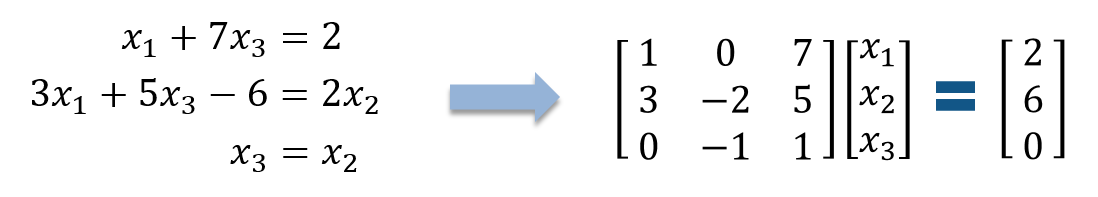

**Definiowanie macierzy współczynników i wektora stałych**

Najpierw zdefiniuj macierz współczynników **A** oraz wektor **b** w MATLAB:

A = [1 0 7; 3 -2 5; 0 -1 1];
b = [2; 6; 0];

**A** to macierz współczynników równania.

**b** to wektor wartości po prawej stronie równań.

**Rozwiązywanie układu równań**

Aby obliczyć wartość wektora **x**, wystarczy użyć operatora `\`:

x = A\b

x =      2
     0
     0


Należy zwrócić uwagę, czy macierz **A** jest kwadratowa dla układów z dokładnym rozwiązaniem.

W przypadku problemów z zbieżnościami wyników, należy zwrócić uwagę, czy układ równań jest układem przeciążonym lub niedookreślonym.

Iterpretacja fizyczna lub matematyczna wyników – nalęzy sprawdzić czy są zgodne z oczekiwaniami i teorią układów równań.

**Przykład 3 (SYMS)**

Zdefiniujmy przykładowy układ równań liniowych:

syms x y z
eqn1 = y + z == -1;
eqn2 = y - 2*z == 2;
eqn3 = -x + 3*z == 1;


Wyświetl równania

disp("Układ równań liniowych:")

Układ równań liniowych:


disp([eqn1; eqn2; eqn3])

$$\left(\begin{array}{c} y+z=-1\\ y-2\,z=2\\ 3\,z-x=1 \end{array}\right)$$

Przedstawienie macierzowe układów liniowych


% Aby przedstawić układ w postaci macierzowej, zdefiniuj macierz współczynników
% `A` oraz wektor stałych `b`. W tej postaci:
%     A * x = b
% gdzie `x` jest wektorem kolumnowym zmiennych, `b` to wektor stałych, a `A`
% to macierz współczynników.


Definicja macierzy współczynników A i wektora b

A = [-1 0 3; 0 1 1; 0 1 -2];
b = [1; -1; 2];


Wyświetlenie postaci macierzowej

disp("Postać macierzowa:")

Postać macierzowa:


disp("A = ")

A = 


disp(A)

    -1     0     3
     0     1     1
     0     1    -2



disp("b = ")

b = 


disp(b)

     1
    -1
     2



Rozwiązywanie układu za pomocą redukcji wierszy


% MATLAB udostępnia funkcje do bezpośredniego rozwiązywania układów równań.
% Możemy użyć funkcji `linsolve` lub dzielenia macierzy, aby rozwiązać równanie
% Ax = b.


Rozwiązywanie za pomocą operatora lewostronnego dzielenia (backslash)

x_sol = A\b;


Wyświetlenie rozwiązania

disp("Rozwiązanie (x, y, z) = ")

Rozwiązanie (x, y, z) = 


disp(x_sol)

    -4
     0
    -1



Metoda macierzy odwrotnej


% Dla układów, gdzie `A` jest odwracalna, możemy także użyć macierzy odwrotnej
% do rozwiązania równania:
%     x = A^(-1) * b

Obliczmy rozwiązanie przy użyciu macierzy odwrotnej.


A_inv = inv(A);  % Oblicz odwrotność macierzy A
x_sol_inverse = A_inv * b;


Wyświetlenie rozwiązania

disp("Rozwiązanie przy użyciu odwrotności (x, y, z) = ")

Rozwiązanie przy użyciu odwrotności (x, y, z) = 


disp(x_sol_inverse)

   -4.0000
   -0.0000
   -1.0000



Wyznacznik i odwracalność macierzy.

Wyznacznik macierzy pozwala określić, czy układ posiada jednoznaczne rozwiązanie. Macierz jest odwracalna, jeśli jej wyznacznik jest różny od zera.


detA = det(A);  % Oblicz wyznacznik macierzy A
disp("Wyznacznik macierzy A:")

Wyznacznik macierzy A:


disp(detA)

     3




% Sprawdź, czy układ ma jednoznaczne rozwiązanie
if detA ~= 0
    disp("Układ ma jednoznaczne rozwiązanie.")
else
    disp("Układ nie ma jednoznacznego rozwiązania.")
end

Układ ma jednoznaczne rozwiązanie.


## Przykład wykorzystania układu równań liniowych

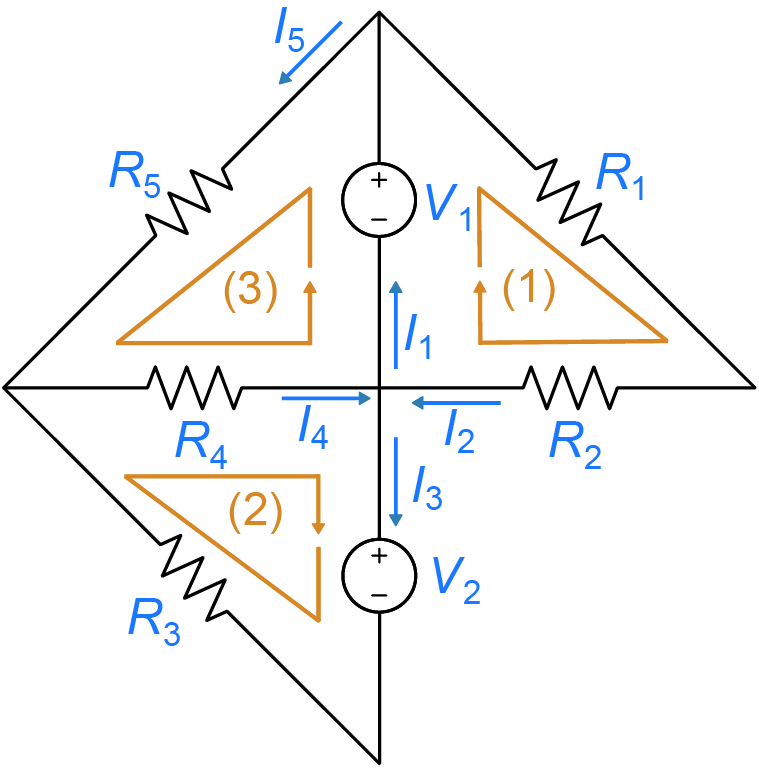

Rysunek 1. Przykładowy schemat obwodu elektrycznego

Na Rysunku 1 są trzy zamknięte pętle obwodu oznaczone (1), (2) i (3).

Poszczególne prądy w obwodzie są oznaczone I1, I2, I3, I4.

Zastosowanie prawa Kirchhoffa prądu do węzła centralnego daje:


$$I_2 + I_4 = I_1 + I_3$$


Zastosowanie drugiego prawa Kirchhoffa (napięciowego) do trzech pętli powoduje dodanie trzech dodatkowych równań:


$$\begin{array}{rl} 
\ V_1 - I_2 R_1 - I_2 R_2  &= 0
\\
- V_2 - I_3 R_3 - I_4 R_4  &= 0
\\
\ V_1 - I_5 R_5 - I_4 R_4  &= 0
\end{array}$$


Jest pięć nieznanych prądów, ale tylko cztery równania. Aby dokończyć reprezentację, wymagane jest kolejne zastosowanie prawa prądów Kirchhoffa. Dla górnego węzła:


$$I_1 = I_2 + I_5$$


Należy pamiętać, że istnieją dodatkowe pętle i węzły, do których można zastosować prawo Kirchhoffa – jednak wszystkie one spowodują wystąpienie powtarzających się warunków.

Na podstawie Prawa Kirchhoffa definiujemy układ równań liniowych, gdzie każdy węzeł i gałąź są reprezentowane przez równanie, a rezystancje i napięcia stanowią współczynniki w macierzy. 

**Wyprowadzenie postaci macierzowej równań**

Aby zapisać te równania w postaci macierzowej $\mathbf{AI} = \mathbf{b}$, należy zdefiniować  wektor rozwiązania:

   
$$\mathbf{I} = \left( \matrix{ I_1 \cr I_2 \cr I_3 \cr I_4 \cr I_5 } \right)$$


Przeniesienie wszystkich zmiennych wyrazów na lewą stronę, a stałych wyrazów na prawą stronę otrzymujemy:

  $\begin{array}{rl} 
\ I_2 R_1 + I_2 R_2  &= V_1
\\
I_3 R_3 + I_4 R_4  &=  -V_2
\\
I_5 R_5  + I_4 R_4  &= V_1  
\\
I_1 - I_2 + I_3 - I_4 &= 0
\\
I_1 - I_2 - I_5 &= 0
\end{array}$        (1)

Powyższy układ równań (1) nalezy przekształcic do postaci macierzowej $\mathbf{AI} = \mathbf{b}$:

A = $\left(\begin{array}{ccccc}
0 & R_1 +R_2  & 0 & 0 & 0\\
0 & 0 & R_3  & R_4  & 0\\
0 & 0 & 0 & R_4  & R_5 \\
1 & -1 & 1 & -1 & 0\\
1 & -1 & 0 & 0 & -1
\end{array}\right)$

b=$\left(\begin{array}{c}
V_1 \\
-V_2 \\
V_1 \\
0\\
0
\end{array}\right)$

Należy obliczyć iloczyn macierzy, aby sprawdzić, czy forma macierzy jest zgodna z oryginalnym systemem (1).

Poniższy skrypt przekształca układ równań do postaci macierzowej i oblicza prądy w każdej gałęzi obwodu, wykorzystując funkcje MATLAB do rozwiązywania układów równań.

% Parametry obwodu (rezystancja w omach, napięcie w woltach)
R1 = 10; R2 = 200; R3 = 10000; R4 = 2000; R5 = 330;
V1 = 1.5; V2 = 12;

% Macierz współczynników i wektor stałych
A = [
        0,  R1+R2, 0,   0,  0;
        0,  0,     R3,  R4, 0;
        0,  0,     0,   R4, R5;
        1,  -1,    1,   -1, 0;
        1,  -1,    0,   0,  -1;
    ];

b = [
     V1;
    -V2;
     V1;
     0;
     0
    ];

% Rozwiązanie równania prądów w każdej gałęzi
I = A\b;

% Wyświetlanie wyników
disp('Natężenie prodów w gałęziach obwodu wynosi:');

Natężenie prodów w gałęziach obwodu wynosi:


disp(I);

    0.0089
    0.0071
   -0.0013
    0.0005
    0.0018



Podczas cwiczeń laboratoryjnych należy wyznaczyć wartości prądów w każdej gałezi dla zadanego obwodu elektrycznego. 